## v0 Intro

In this scrip we try to use svd to process the cutted experiment data, and figure out the property at the same time.

## Loading and pre-treatment data

%for5s name_list=["n78","n142","p47","p77","p179"];
%for30s name_list=["n78","n142","n589","p47","p77","p179"];
name_list=["n78","n142","n589","p47","p77","p179"]

name_list = 1×6 string 数组
    "n78"    "n142"    "n589"    "p47"    "p77"    "p179"


experiment_interval=30;%s
matrix_processed_MSD=[];
min_length=100;
for i=1:length(name_list)
    name=char(name_list(i));
    load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\processed data ',name,'_',num2str(experiment_interval),'s.mat'])
    min_length=min(reserved_length,min_length);
end
for i=1:length(name_list)
    name=char(name_list(i));
    load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\processed data ',name,'_',num2str(experiment_interval),'s.mat'])
    matrix_processed_MSD=[matrix_processed_MSD;processed_MSD(1:min_length).'];
end

## Calculate svd

[U,S,V]=svd(matrix_processed_MSD);
singular_value=[];
reserved_S=zeros(length(name_list),min_length);
for i=1:length(name_list)
    singular_value=[singular_value,S(i,i)];
    if i<=2
        reserved_S(i,i)=S(i,i);
    end
end
disp(singular_value)

   1.0e+06 *

    4.9899    0.1722    0.0169    0.0098    0.0083    0.0050



smoothed_curve=U*reserved_S*V';
time_scape=experiment_interval*(1:min_length);

## Plotting

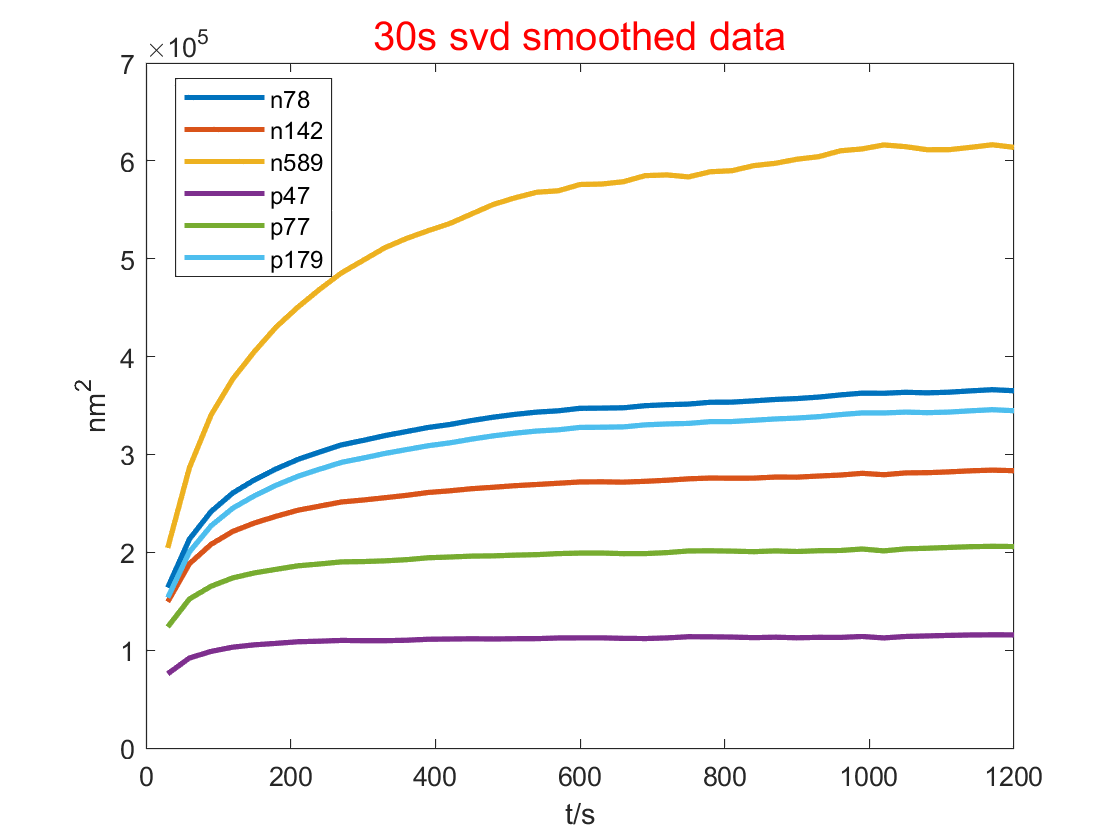

figure
plot(time_scape,smoothed_curve,'LineWidth',2)
legend(name_list,"Location","best")
xlabel(['t/s'])
ylabel('nm^2')
title([num2str(experiment_interval),'s svd smoothed data'],'Fontsize',15,"Color",'r')

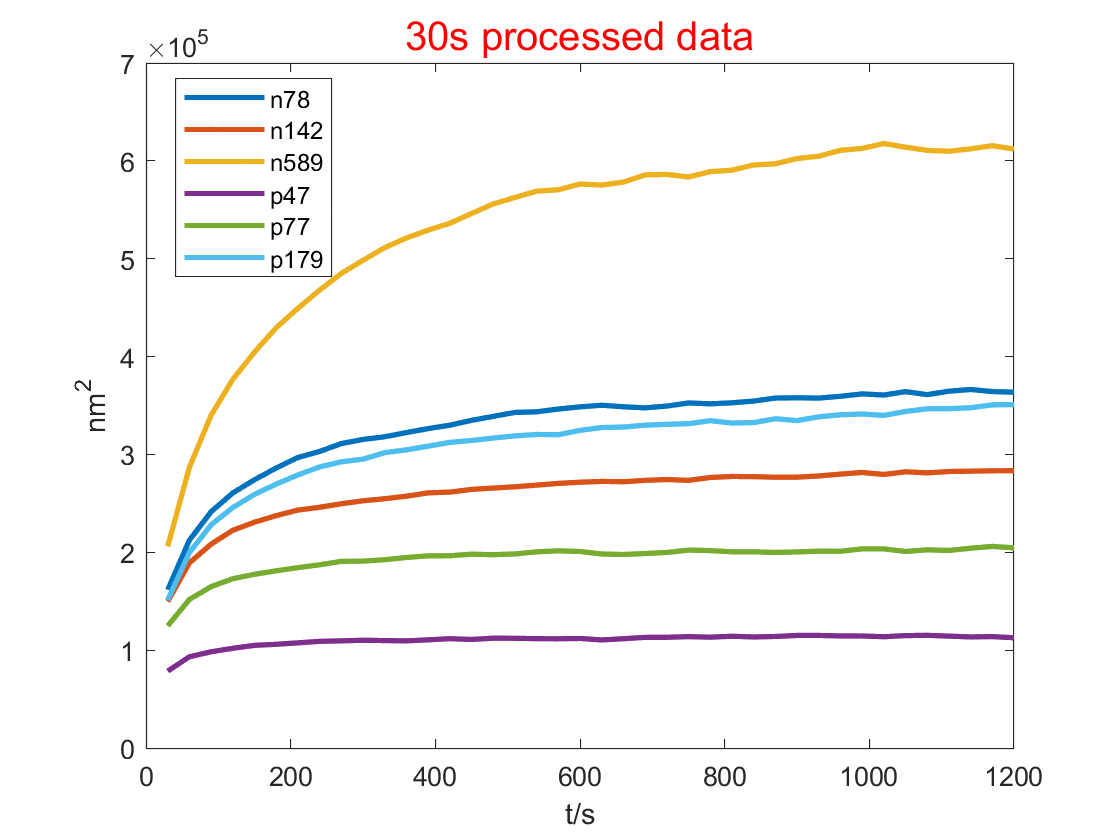

figure
plot(time_scape,matrix_processed_MSD,'LineWidth',2)
legend(name_list,"Location","best")
xlabel(['t/s'])
ylabel('nm^2')
title([num2str(experiment_interval),'s processed data'],'Fontsize',15,"Color",'r')

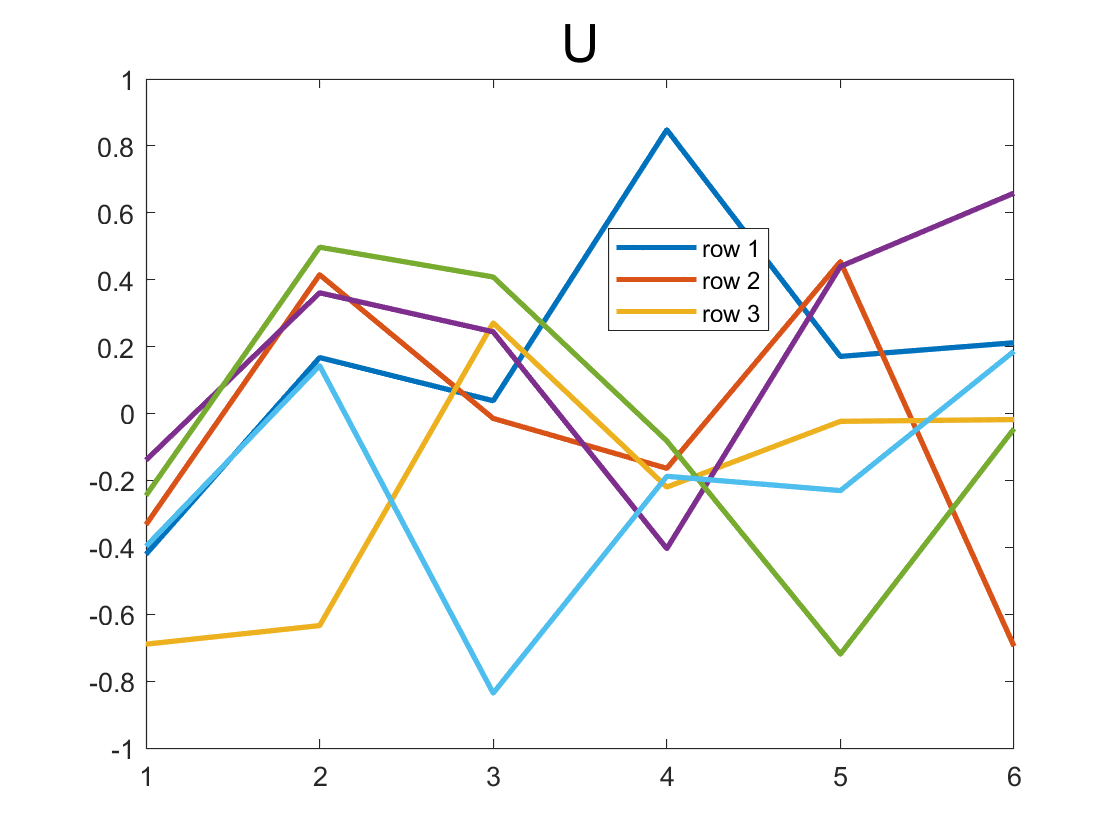


figure
plot(U','LineWidth',2)
legend('row 1','row 2','row 3','location',"best")
title('U','FontSize',20)

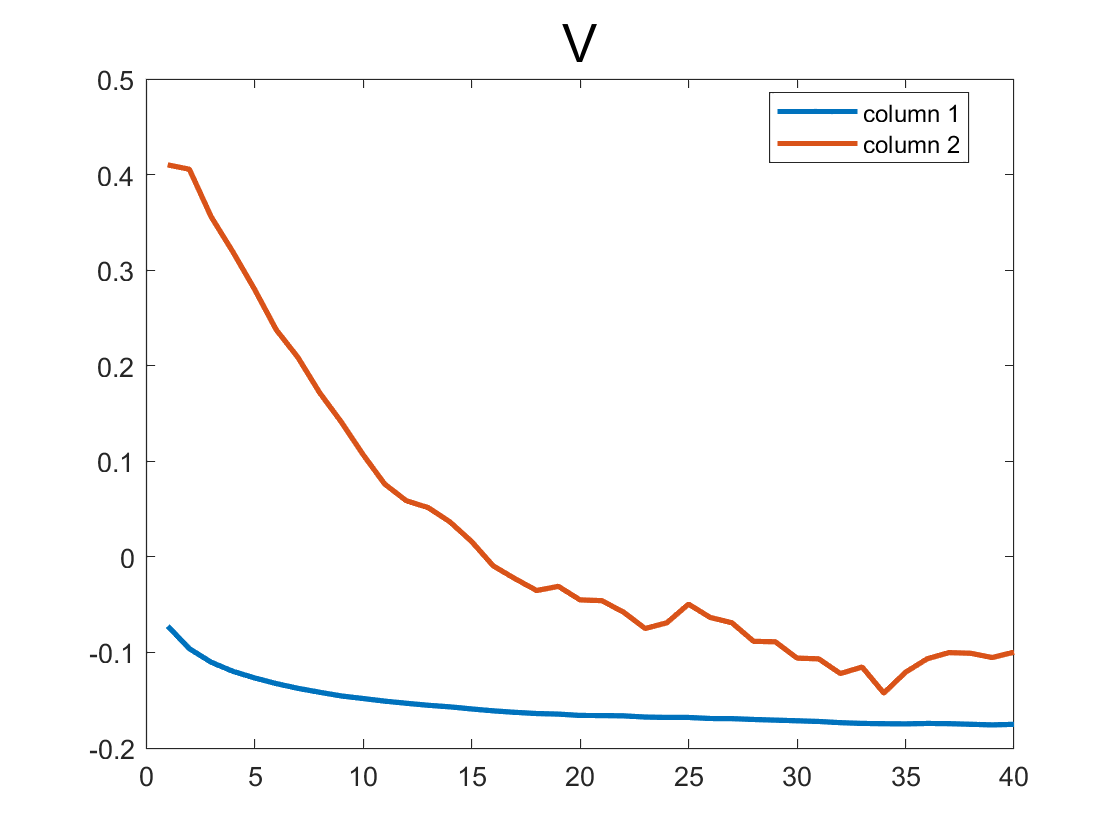

figure
plot(1:length(V),V(:,1),1:length(V),V(:,2),'LineWidth',2)
legend('column 1','column 2','location',"best")
title('V','FontSize',20)